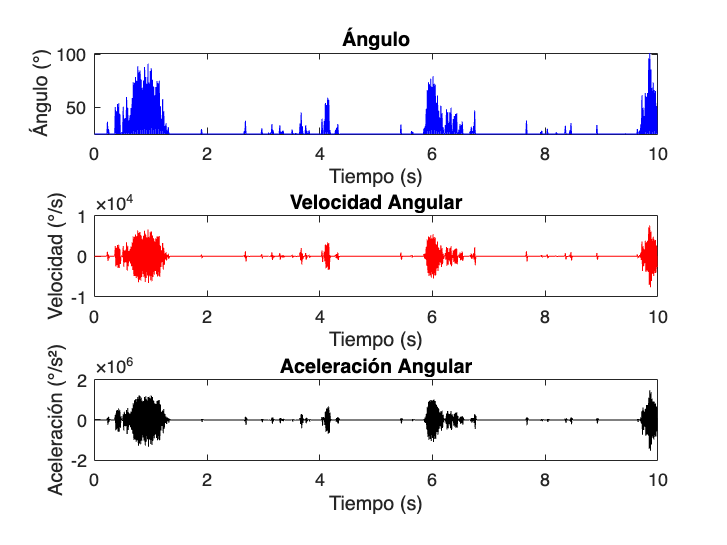

%% Parámetros de simulación
% Rango “crudo” del potenciómetro (lectura en radianes)
raw_min    = 0;
raw_max    = 3*pi/2;

% Rango real del ángulo en grados
angle_min  = 30;
angle_max  = 180;
angle_err  = 5;  % tolerancia

% Calibración
K = 0.1867;    % pendiente
b = -4.573;    % offset

% Simulación temporal
fs  = 100;        % frecuencia de muestreo en Hz
dt  = 1/fs;
n   = 1000;       % número de muestras

% Ruido
sigma_step = 40;  % cambio suave por paso (rad)
sigma_n    = 10;  % ruido gaussiano (rad)

%% Generar datos simulados del potenciómetro (movimiento suave y aleatorio)
raw = zeros(1, n);
raw(1) = (raw_min + raw_max) / 2;

for i = 2:n
    delta = sigma_step * randn;
    raw(i) = raw(i-1) + delta;
    
    % Reflejar si se sale del rango
    if raw(i) > raw_max
        raw(i) = raw_max - (raw(i) - raw_max);
    elseif raw(i) < raw_min
        raw(i) = raw_min + (raw_min - raw(i));
    end
end

%% Añadir ruido gaussiano
raw_noisy = raw + sigma_n * randn(1, n);

%% Calibrar a ángulo en grados
angle = K * raw_noisy + b;
angle = max(min(angle, angle_max + angle_err), angle_min - angle_err);

%% Calcular velocidad y aceleración angular
vel = [0, diff(angle)] / dt;        % grados/s
acc = [0, diff(vel)]   / dt;        % grados/s²

%% Gráficas
t = (0:n-1) * dt;

figure;

subplot(3,1,1);
plot(t, angle, 'b');
xlabel('Tiempo (s)');
ylabel('Ángulo (°)');
title('Ángulo');

subplot(3,1,2);
plot(t, vel, 'r');
xlabel('Tiempo (s)');
ylabel('Velocidad (°/s)');
title('Velocidad Angular');

subplot(3,1,3);
plot(t, acc, 'k');
xlabel('Tiempo (s)');
ylabel('Aceleración (°/s²)');
title('Aceleración Angular');